%Read in images from folder apply blur and save them in the appropriate
%file structure
file = dir(fullfile('images'));
image_count = length(file)-2;
order = randperm(image_count,image_count)+2;
image_count = image_count / 4; %scale sets to not use all images
train_count = round(image_count*.75);
test_break = round(image_count*.8);
val_count = test_break - train_count;
test_count = image_count - test_break;
for k = 1:image_count
    if k <= train_count
        folder = 'train';
        factor = 0;
    elseif k <= test_break
        folder = 'val';
        factor = train_count;
    else
        folder = 'test';
        factor = test_break;
    end
    im = imread(fullfile('images',file(order(k)).name));
    sigma = abs(random('Normal',0,5));
    im_mod = im;
    if sigma > 0
        im_mod = imgaussfilt(im_mod,sigma);
    end
    fnameI = ['blur_reg/input/' folder '/img' num2str(k - factor) '.mat'];
    T = im_mod;
    save(fnameI,'T');
    fnameL = ['blur_reg/label/' folder '/img' num2str(k - factor) '.mat'];
    T = [sigma];
    save(fnameL,'T');
    fnameT = ['blur_reg/true/' folder '/img' num2str(k - factor) '.mat'];
    T = im;
    save(fnameT,'T');
    if strcmp(folder,'val')
        imwrite(im,fullfile('TestImages',['img' num2str(k-factor) '.png']))
    end
end
s = size(im);

%load train, test, val set
trainInput=fileDatastore(fullfile('blur_reg','input','train'),'ReadFcn',@load,'FileExtensions','.mat');
trainTarget=fileDatastore(fullfile('blur_reg','label','train'),'ReadFcn',@load,'FileExtensions','.mat');
trainTrue=fileDatastore(fullfile('blur_reg','true', 'train'),'ReadFcn',@load,'FileExtensions','.mat');

testInput=fileDatastore(fullfile('blur_reg','input','test'),'ReadFcn',@load,'FileExtensions','.mat');
testTarget=fileDatastore(fullfile('blur_reg','label','test'),'ReadFcn',@load,'FileExtensions','.mat');
testTrue=fileDatastore(fullfile('blur_reg','true', 'test'),'ReadFcn',@load,'FileExtensions','.mat');

valInput=fileDatastore(fullfile('blur_reg','input','val'),'ReadFcn',@load,'FileExtensions','.mat');
valTarget=fileDatastore(fullfile('blur_reg','label','val'),'ReadFcn',@load,'FileExtensions','.mat');
valTrue=fileDatastore(fullfile('blur_reg','true', 'val'),'ReadFcn',@load,'FileExtensions','.mat');

%transform
trainInputT = transform(trainInput,@(data) rearrange_datastore(data));
trainTargetT = transform(trainTarget,@(data) rearrange_datastore(data));
trainTrueT = transform(trainTrue,@(data) rearrange_datastore(data));

testInputT = transform(testInput,@(data) rearrange_datastore(data));
testTargetT = transform(testTarget,@(data) rearrange_datastore(data));
testTrueT = transform(testTrue,@(data) rearrange_datastore(data));

valInputT = transform(valInput,@(data) rearrange_datastore(data));
valTargetT = transform(valTarget,@(data) rearrange_datastore(data));
valTrueT = transform(valTrue,@(data) rearrange_datastore(data));

%combine input and label
trainData = combine(trainInputT,trainTargetT);
valData = combine(valInputT,valTargetT);
testData = combine(testInputT,testTargetT);

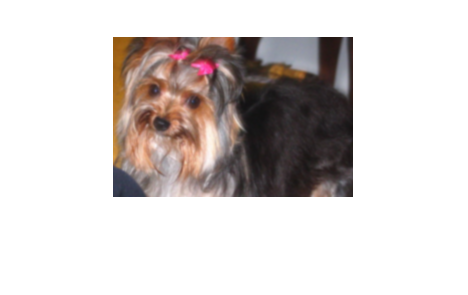

%Check images
im = trainInputT.read();
im = im{1};
imshow(im);

sigma = trainTargetT.read();
sigma = sigma{1}    

sigma = 0.8503

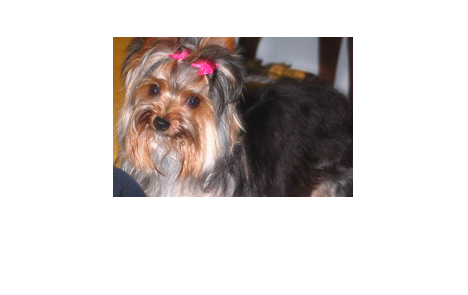

true = trainTrueT.read();
true = true{1};
imshow(true)

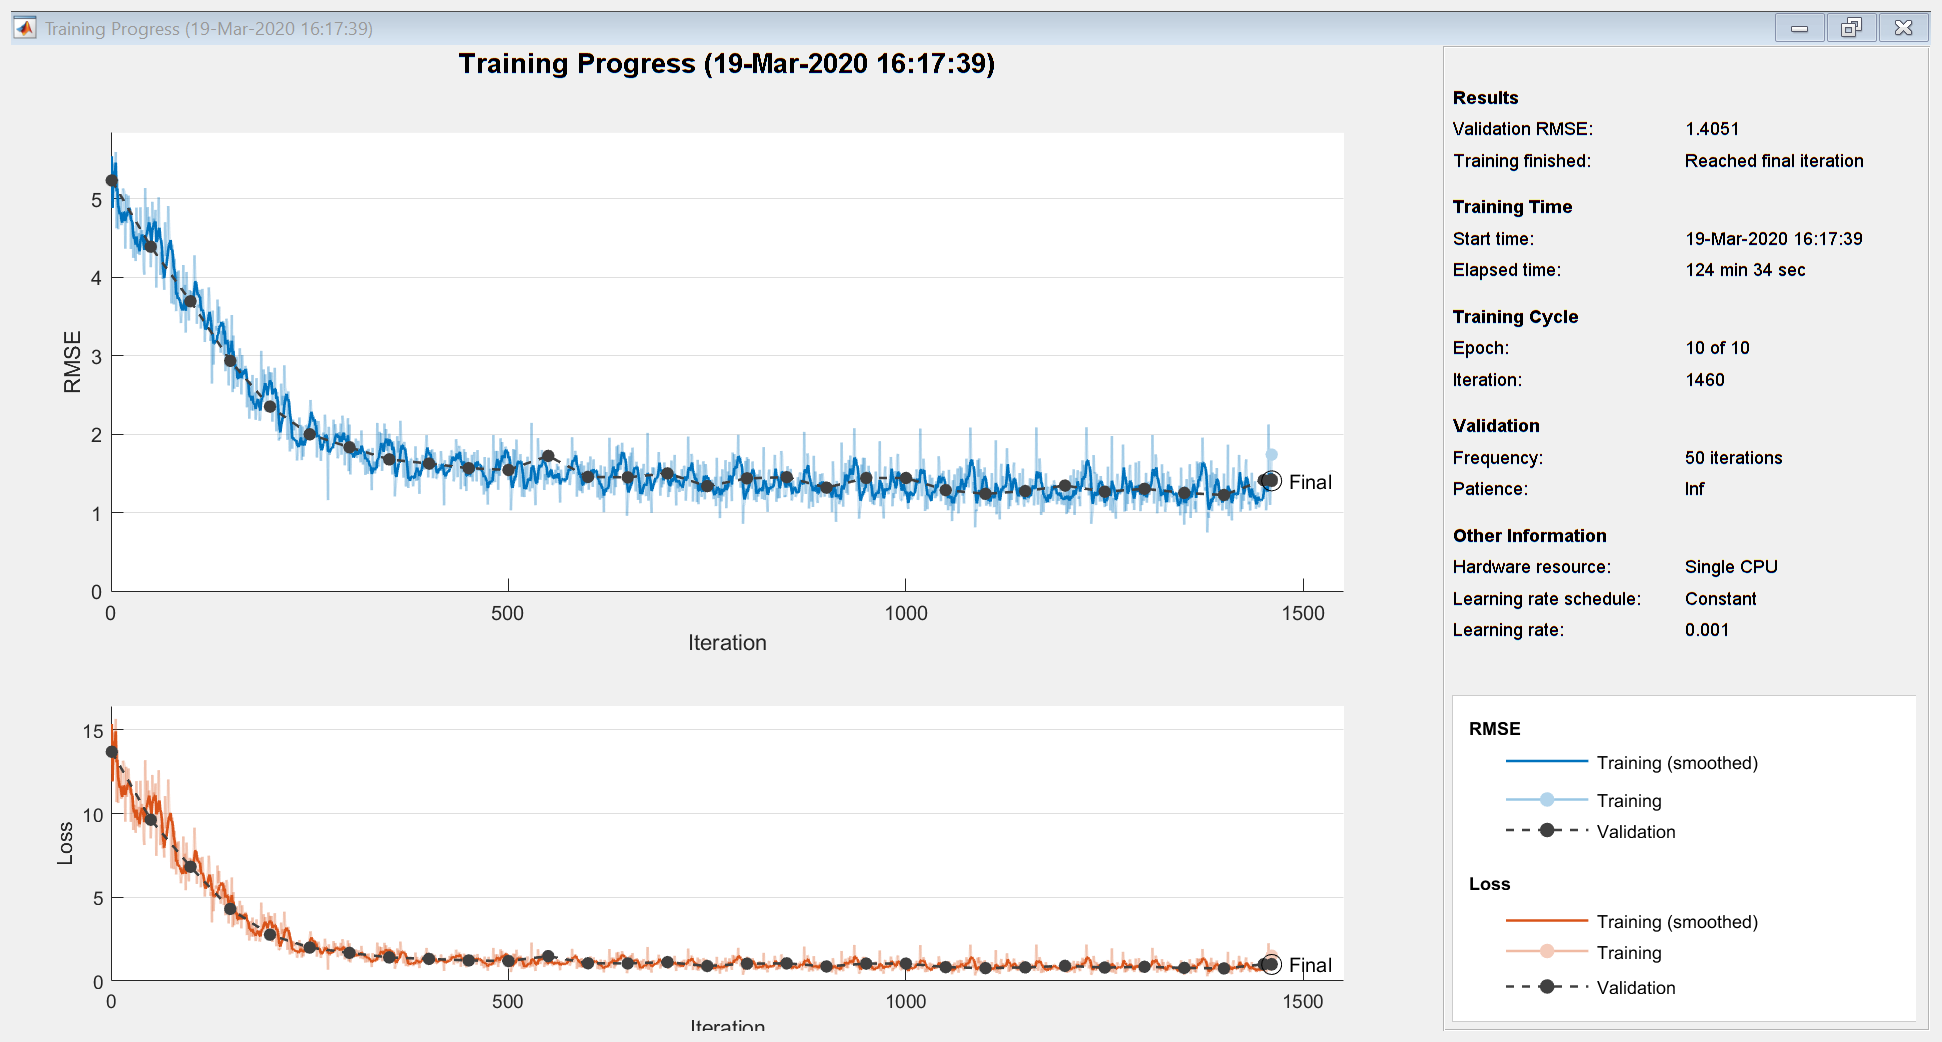

% set up model
layers = [
    imageInputLayer([160 240 3])
    
    convolution2dLayer(3,10,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2)
    
    convolution2dLayer(3,20,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2)
    
    convolution2dLayer(3,30,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];
maxEpochs = 10;
options = trainingOptions('sgdm', ...
    "Momentum", .75, ...
    'MiniBatchSize',64, ...
    'MaxEpochs',maxEpochs, ...
    'InitialLearnRate',1e-3, ...
    'Plots','training-progress', ...
    'GradientThreshold',2, ...
    'ValidationData',valData, ...
    'Shuffle','never',...
    'Verbose',false);
net = trainNetwork(trainData,layers,options);

modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
save(['blur_reg/Regression trainedNet-' modelDateTime '-Epoch-' num2str(maxEpochs) ...
            'ScaleFactors-' num2str(234) '.mat'],'net','options');

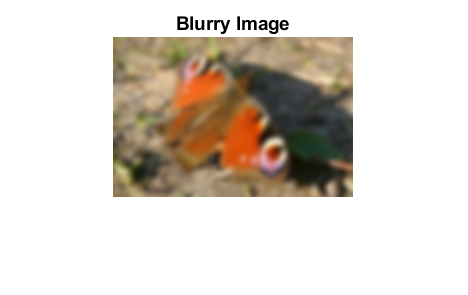

%Check prediction on a random sample
im = testTrueT.read();
im = im{1};
im_test = testInputT.read();
im_test = im_test{1};

figure; imshow(im_test)
title('Blurry Image');

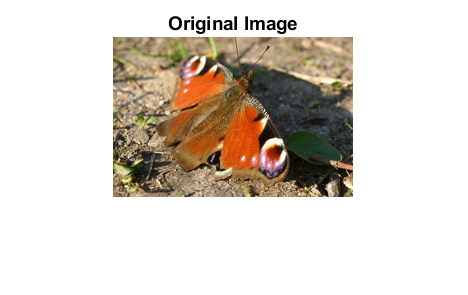


figure; imshow(im);
title('Original Image');


net.predict(im_test)

ans = single
2.4464

test_sigma = testTargetT.read();
test_sigma = test_sigma{1}

test_sigma = 2.7793

%Calculate RMSE on training set
preds = predict(net,trainInputT);
actual = cell2mat(trainTargetT.readall());
error = preds - actual;
rmse = sqrt(mean(error.^2))

rmse = single
0.9448

function image = rearrange_datastore(data)
image=data.T;
image= {image};
end